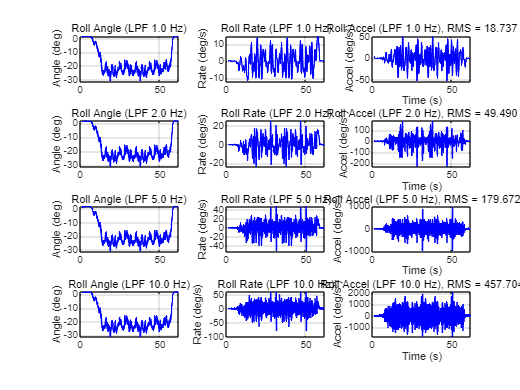

% === Load IMU Data ===
data = readtable('imu1.csv');
t = data.Time_ms / 1000;
dt = mean(diff(t));
fs = 1 / dt;

% === Raw Sensor Data ===
Gy = data.GyroY_degps;
Ay = data.AccelY_g * 9.80665;
Az = data.AccelZ_g * 9.80665;

% === Acc-based Roll Angle ===
acc_roll = atan2(Ay, Az);  % rad

% === Complementary Filter for Roll Angle ===
alpha = 0.98;
Gy_rad = Gy * pi/180;

% === Cutoff frequencies to analyze ===
cutoff_list = [1, 2, 5, 10];
rms_result = zeros(size(cutoff_list));

% === Plotting and RMS per cutoff ===
figure;
for i = 1:length(cutoff_list)
    fc = cutoff_list(i);

    % --- Complementary Filter Angle ---
    roll_rad = zeros(size(t));
    roll_rad(1) = acc_roll(1);
    for k = 2:length(t)
        gyro_delta = Gy_rad(k) * dt;
        predicted = roll_rad(k-1) + gyro_delta;
        roll_rad(k) = alpha * predicted + (1 - alpha) * acc_roll(k);
    end

    % --- Roll Rate (rad/s) ---
    roll_rate = [0; diff(roll_rad)] / dt;

    % --- LPF on rate ---
    [b, a] = butter(4, fc / (fs/2), 'low');
    roll_rate_filt = filtfilt(b, a, roll_rate);

    % --- Roll Acceleration (rad/s²) ---
    roll_acc = [0; diff(roll_rate_filt)] / dt;

    % --- Convert all to deg units ---
    roll_deg    = roll_rad * 180/pi;
    roll_rate_d = roll_rate_filt * 180/pi;
    roll_acc_d  = roll_acc * 180/pi;

    % --- RMS 저장 ---
    rms_result(i) = rms(roll_acc_d);

    % --- Plot (모두 파란색) ---
    subplot(length(cutoff_list), 3, 3*(i-1)+1);
    plot(t, roll_deg, 'b', 'LineWidth', 1.2);
    ylabel('Angle (deg)');
    title(sprintf('Roll Angle (LPF %.1f Hz)', fc));
    grid on;

    subplot(length(cutoff_list), 3, 3*(i-1)+2);
    plot(t, roll_rate_d, 'b', 'LineWidth', 1.2);
    ylabel('Rate (deg/s)');
    title(sprintf('Roll Rate (LPF %.1f Hz)', fc));
    grid on;

    subplot(length(cutoff_list), 3, 3*(i-1)+3);
    plot(t, roll_acc_d, 'b', 'LineWidth', 1.2);
    ylabel('Accel (deg/s²)');
    xlabel('Time (s)');
    title(sprintf('Roll Accel (LPF %.1f Hz), RMS = %.3f', fc, rms_result(i)));
    grid on;
end


% === Summary Table ===
T_rms = table(cutoff_list', rms_result', ...
    'VariableNames', {'LPF_Hz', 'Roll_Accel_RMS_degps2'});
disp(T_rms);

    LPF_Hz    Roll_Accel_RMS_degps2
    ______    _____________________

       1             18.737        
       2              49.49        
       5             179.67        
      10              457.7        

